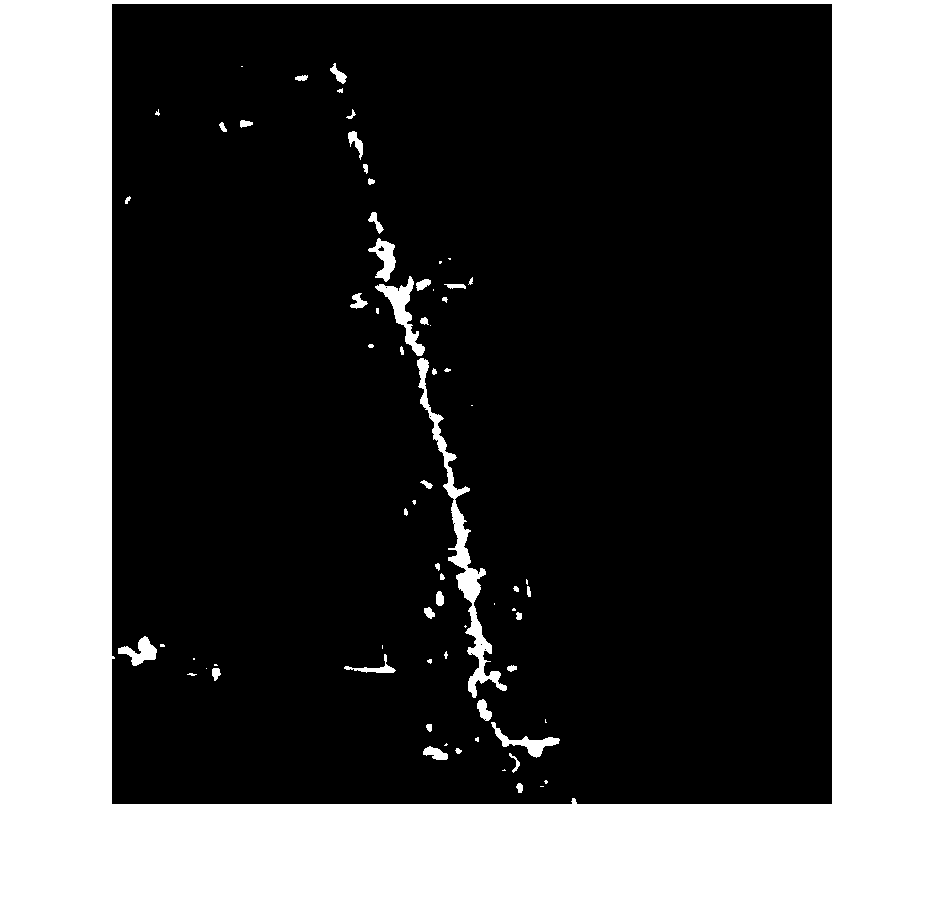

clear;
M = 800; N = 720; num = 5;
Images = zeros(num, M, N, 3); %instantiate Images array
%get all images 
Images(1,:,:,:) = imread("imageSeries1_year2000.jpg");
Images(2,:,:,:) = imread("imageSeries1_year2004.jpg");
Images(3,:,:,:) = imread("imageSeries1_year2008.jpg");
Images(4,:,:,:) = imread("imageSeries1_year2012.jpg");
Images(5,:,:,:) = imread("imageSeries1_year2016.jpg");
Images = uint8(Images);
area = getArea(Images(1,:,:,:)); %area (km) same for all images

MaskedImages = getMasks(Images, [0 .21; 0 1;  0 .791]); %create masked images
deforestPercent = percentWhite(MaskedImages); %get percentage of white in masked images
deforestArea = deforestPercent*area;


imshow(squeeze(MaskedImages(1,:,:)))
title('2000')

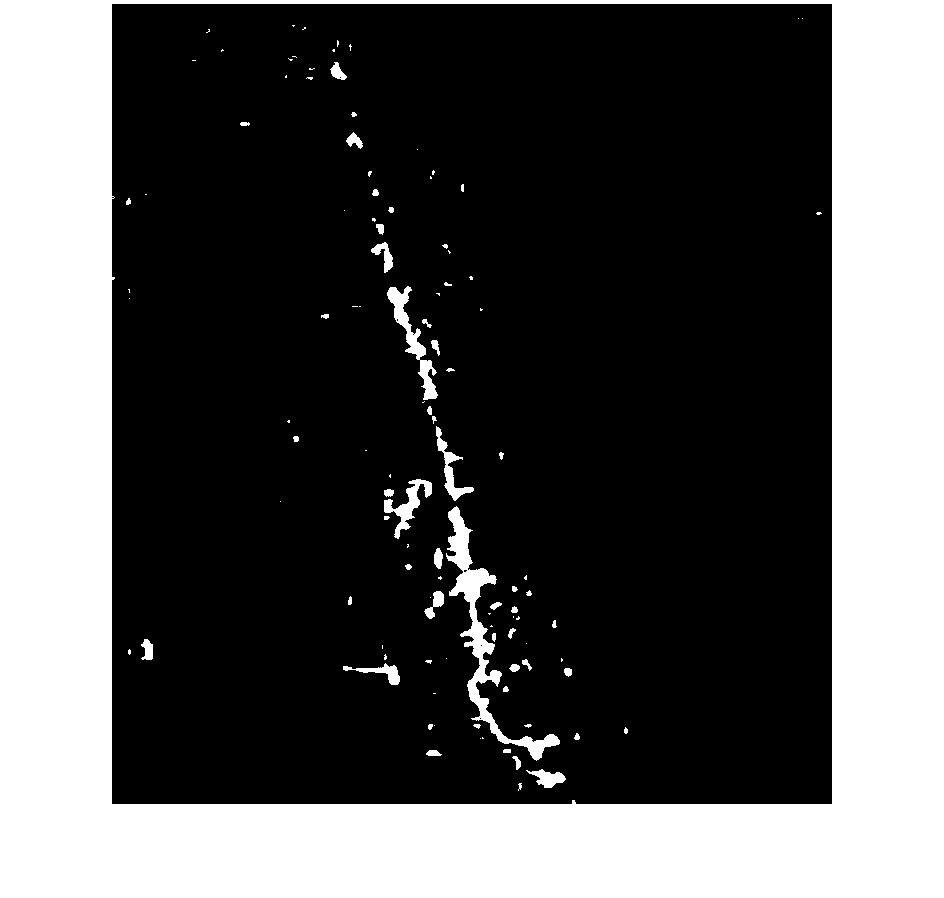

imshow(squeeze(MaskedImages(2,:,:)))
title('2004')

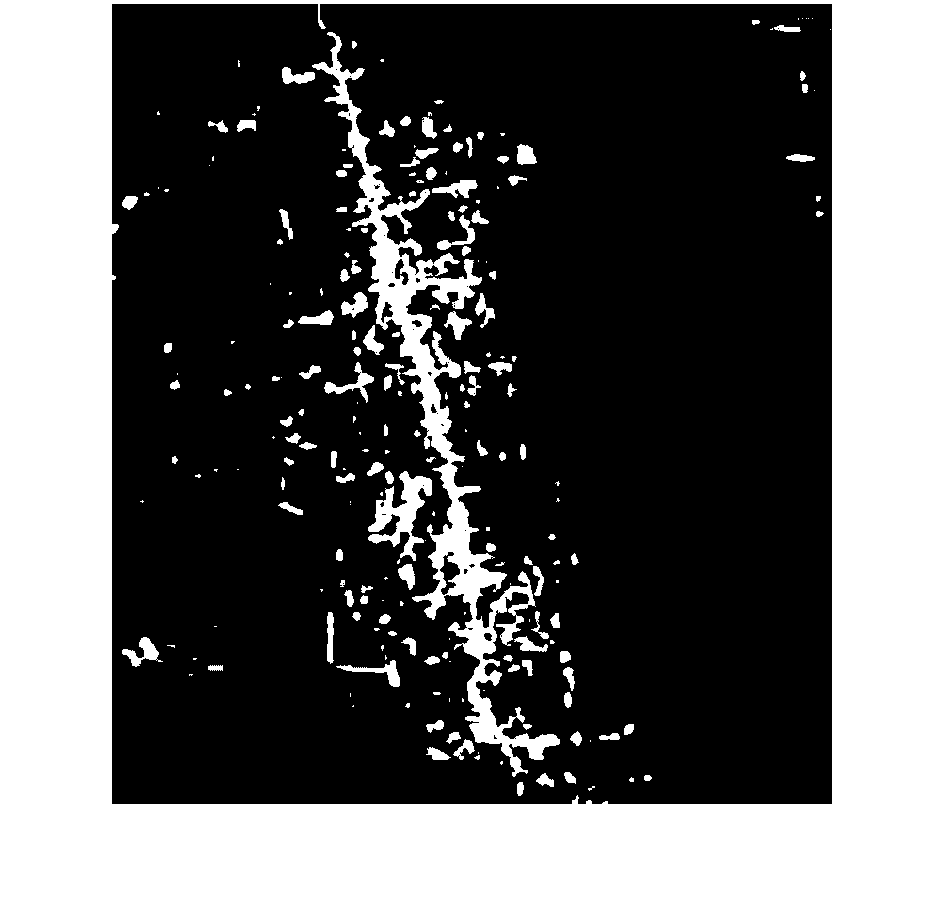

imshow(squeeze(MaskedImages(3,:,:)))
title('2008')

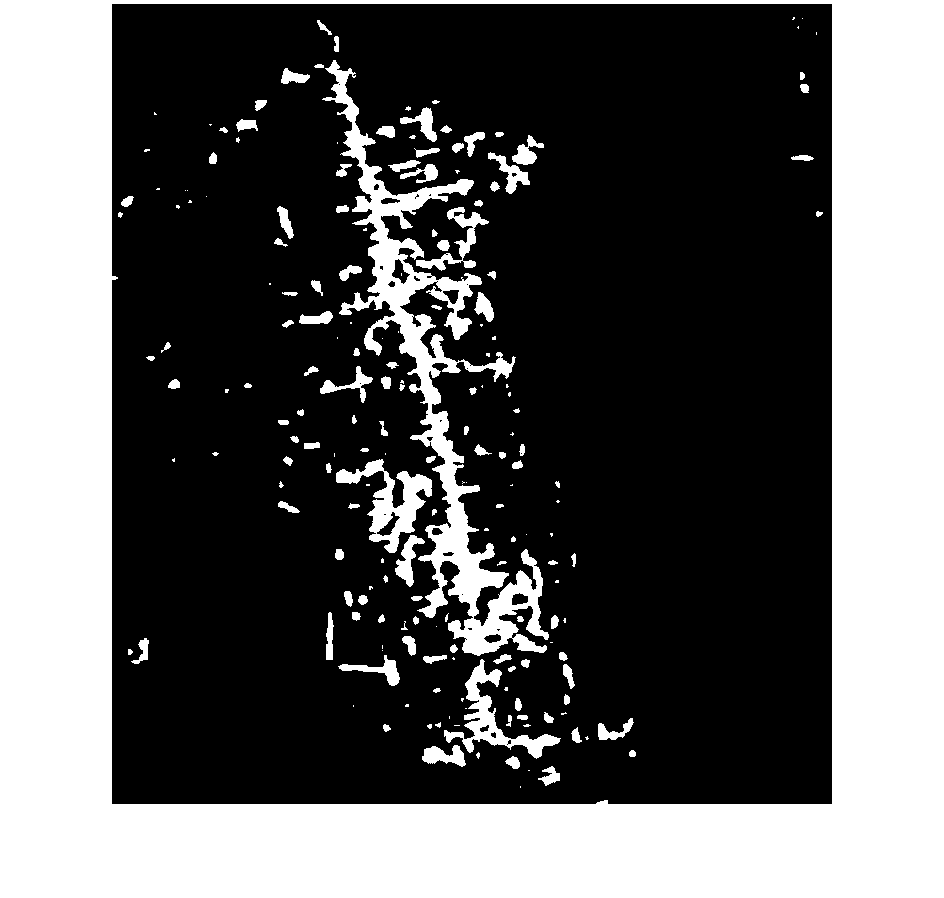

imshow(squeeze(MaskedImages(4,:,:)))
title('2012')

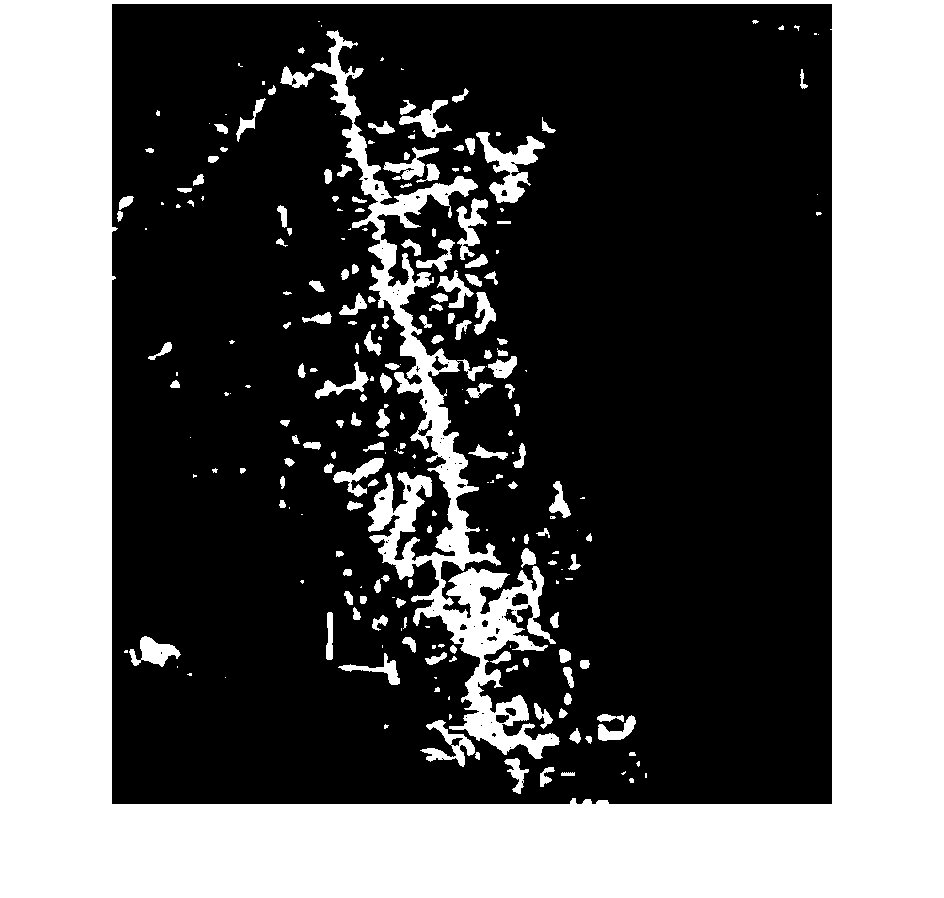

imshow(squeeze(MaskedImages(5,:,:)))
title('2016')

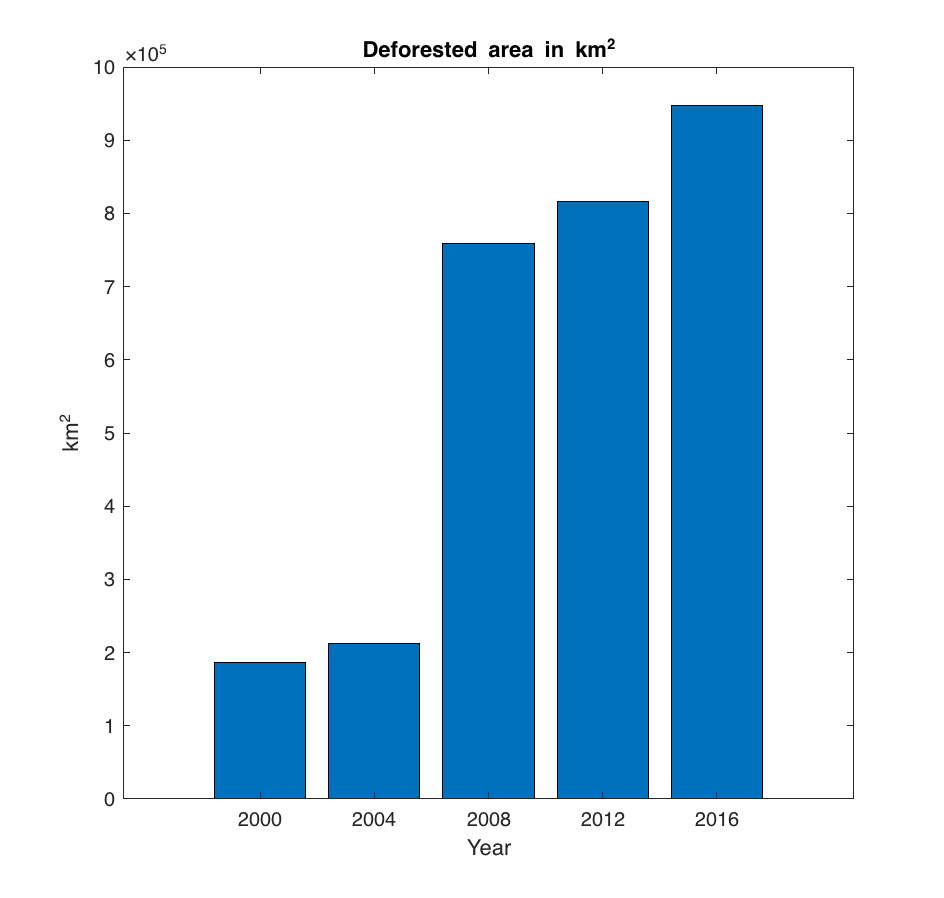


years = 2000:4:2016;
bar(years, deforestArea);
title("Deforested area in km^2")
xlabel("Year")
ylabel("km^2")